clear
clc
close all

x = 0:0.05:3*pi; t = sin(x.^2);
%x = 0:0.02:3*pi; t = sin(x.^2);
t = awgn(t,15,'measured');                %uncomment to add additive white gaussian noise

mse_br_lm = zeros(1,2);
regress_br_lm = zeros(1,2);
epochs_br_lm = zeros(1,2);

for j=1:20
    
    %initialising networks
    br_net = fitnet(30, 'trainbr');
    lm_net = fitnet(30, 'trainlm');
    nets = {br_net, lm_net};
    
    for i = 1:length(nets)                        
        nets{i}.iw{1,1}=br_net.iw{1,1}; %set the same weights and biases for the networks 
        nets{i}.lw{2,1}=br_net.lw{2,1};
        
        nets{i}.b{1}=br_net.b{1};
        nets{i}.b{2}=br_net.b{2};  
    end
    
    %training networks with 100 epochs
    br_net.trainParam.epochs=100;
    lm_net.trainParam.epochs=100;
    
    [br_net, br_tr] = train(br_net, x, t);
    [lm_net, lm_tr] = train(lm_net, x, t);
    
    %estimating targets using trained networks
    y_br = br_net(x);
    y_lm = lm_net(x);
    
    %assessing performances of networks with MSE
    br_test_perf = br_tr.best_tperf;
    lm_test_perf = lm_tr.best_tperf;
    test_perfs = [br_test_perf lm_test_perf];
    mse_br_lm(j,:) = test_perfs;
    
    %regression performance of networks
    r_br = abs(regression(y_br,t));
    r_lm = abs(regression(y_lm,t));
    regress = [r_br r_lm];
    regress_br_lm(j,:) = regress;
    
    % Number of epochs until convergence
    epoch_br = br_tr.best_epoch;
    epoch_lm = lm_tr.best_epoch;
    best_epochs = [epoch_br epoch_lm];
    epochs_br_lm(j,:) = best_epochs;
end

average_regress = mean(regress_br_lm, 1)

average_regress =     0.9632    0.8048


average_mse = mean(mse_br_lm, 1)

average_mse =     0.0668    0.2571


average_epochs = mean(epochs_br_lm, 1)

average_epochs =    97.2500    9.4000


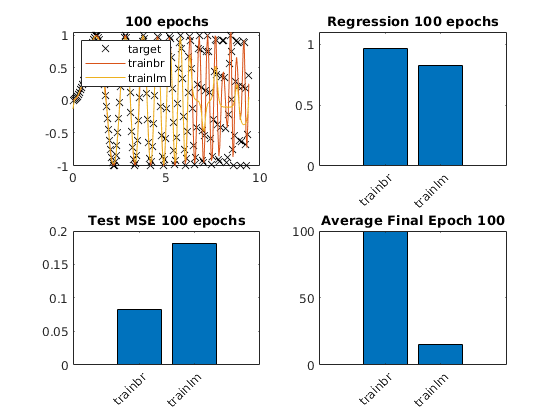

%plotting
algorithm = {'trainbr' 'trainlm'};

figure
subplot(2,2,1);
plot(x,t,'kx',x, y_br,x,y_lm); % plot the sine function and the output of the networks
title('100 epochs');
legend('target','trainbr','trainlm','Location','northwest');

subplot(2,2,2);
b = bar(average_regress,'FaceColor','flat');
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.1]);
title('Regression 100 epochs');

subplot(2,2,3);
b = bar(average_mse,'FaceColor','flat');
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Test MSE 100 epochs');

subplot(2,2,4);
b = bar(average_epochs,'FaceColor','flat');
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Average Final Epoch 100');

Overparametrised

clear
clc
close all

x = 0:0.05:3*pi; t = sin(x.^2);
%x = 0:0.02:3*pi; t = sin(x.^2);
t = awgn(t,15,'measured');                %uncomment to add additive white gaussian noise

mse_br_lm = zeros(10,2);
regress_br_lm = zeros(10,2);
epochs_br_lm = zeros(10,2);

for j=1:20
    
    %initialising networks
    br_net = fitnet(100, 'trainbr');
    lm_net = fitnet(100, 'trainlm');
    nets = {br_net, lm_net};
    
    for i = 1:length(nets)                        
        nets{i}.iw{1,1}=br_net.iw{1,1}; %set the same weights and biases for the networks 
        nets{i}.lw{2,1}=br_net.lw{2,1};
        
        nets{i}.b{1}=br_net.b{1};
        nets{i}.b{2}=br_net.b{2};  
    end
    
    %training networks with 100 epochs
    br_net.trainParam.epochs=100;
    lm_net.trainParam.epochs=100;
    
    [br_net, br_tr] = train(br_net, x, t);
    [lm_net, lm_tr] = train(lm_net, x, t);
    
    %estimating targets using trained networks
    y_br = br_net(x);
    y_lm = lm_net(x);
    
    %assessing performances of networks with MSE
    br_test_perf = br_tr.best_tperf;
    lm_test_perf = lm_tr.best_tperf;
    test_perfs = [br_test_perf lm_test_perf];
    mse_br_lm(j,:) = test_perfs;
    
    %regression performance of networks
    r_br = abs(regression(y_br,t));
    r_lm = abs(regression(y_lm,t));
    regress = [r_br r_lm];
    regress_br_lm(j,:) = regress;
    
    
    epoch_br = br_tr.best_epoch;
    epoch_lm = lm_tr.best_epoch;
    best_epochs = [epoch_br epoch_lm];
    epoch_br_lm(j,:) = best_epochs;
end

average_regress = mean(regress_br_lm, 1);
average_mse = mean(mse_br_lm, 1);
average_epochs = mean(epoch_br_lm, 1);

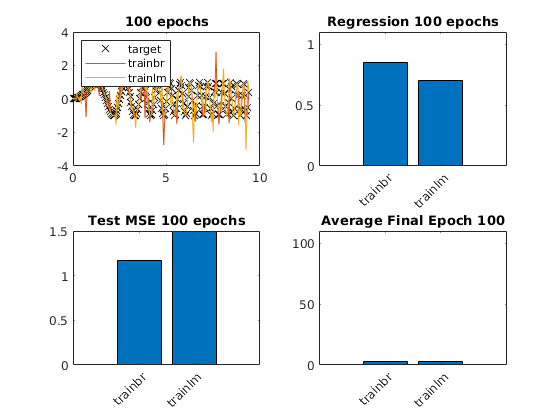

%plotting
algorithm = {'trainbr' 'trainlm'};

figure
subplot(2,2,1);
plot(x,t,'kx',x, y_br,x,y_lm); % plot the sine function and the output of the networks
title('100 epochs');
legend('target','trainbr','trainlm','Location','northwest');

subplot(2,2,2);
b = bar(average_regress,'FaceColor','flat');
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.1]);
title('Regression 100 epochs');

subplot(2,2,3);
b = bar(average_mse,'FaceColor','flat');
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Test MSE 100 epochs');

subplot(2,2,4);
b = bar(average_epochs,'FaceColor','flat');
set(gca, 'xticklabel',algorithm);
ylim([0 110]);
xtickangle(45);
title('Average Final Epoch 100');

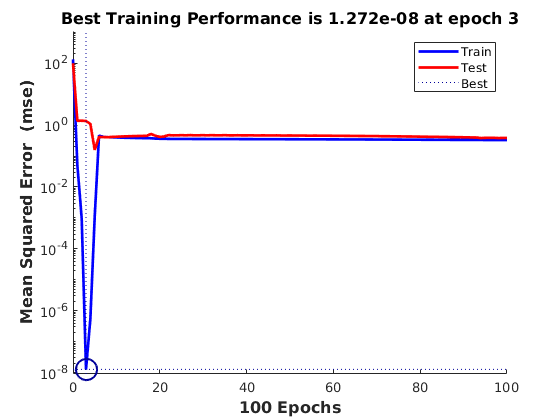

%initialising networks
br_net = fitnet(400, 'trainbr');
lm_net = fitnet(400, 'trainlm');
nets = {br_net, lm_net};

for i = 1:length(nets)                        
    nets{i}.iw{1,1}=br_net.iw{1,1}; %set the same weights and biases for the networks 
    nets{i}.lw{2,1}=br_net.lw{2,1};
    
    nets{i}.b{1}=br_net.b{1};
    nets{i}.b{2}=br_net.b{2};  
end

%training networks with 100 epochs
br_net.trainParam.epochs=100;
lm_net.trainParam.epochs=100;

[br_net, br_tr] = train(br_net, x, t);
[lm_net, lm_tr] = train(lm_net, x, t);

plotperform(br_tr);

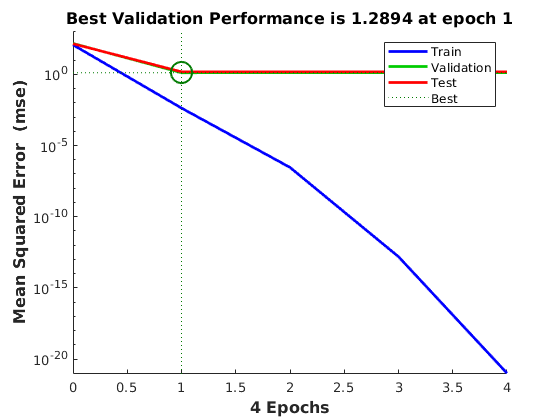

plotperform(lm_tr);